## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from FDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## Import data and previewing

The data come from expomential fitness data.

data_name='n589';
selecting_curve='xy';
experiment_interval=30;

load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',data_name,'_',num2str(experiment_interval),'s.mat'])

min_length=40;
time_scale=experiment_interval*(1:min_length);




fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=5.385e+05;%n589_30s
a(2)=0.0001211;
a(3)=-3.902e+05;
a(4)=-0.006544;   

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Parameter importing

input=[1.45732518427729e-06,	0.624564619339754	,1.09373098598108e-14];
a=input(1);%m
Gamma=input(2);
K_gamma=input(3);

## Main loop

simulation_MSD=[];
for t=experiment_interval*[1:min_length]
    sum_number=10;
    sum_list=zeros(sum_number,1);
    for m=1:sum_number
        sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
    end
    simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

## Plot and saving

figure
hold on
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
plot(time_scale,1e-18*processed_MSD(1:min_length),'+',"DisplayName",'experiment xy average data',"Color",'cyan',"LineWidth",1)
legend_name=strcat('FDE simulation MSD',' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & PDE simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');

## Saving

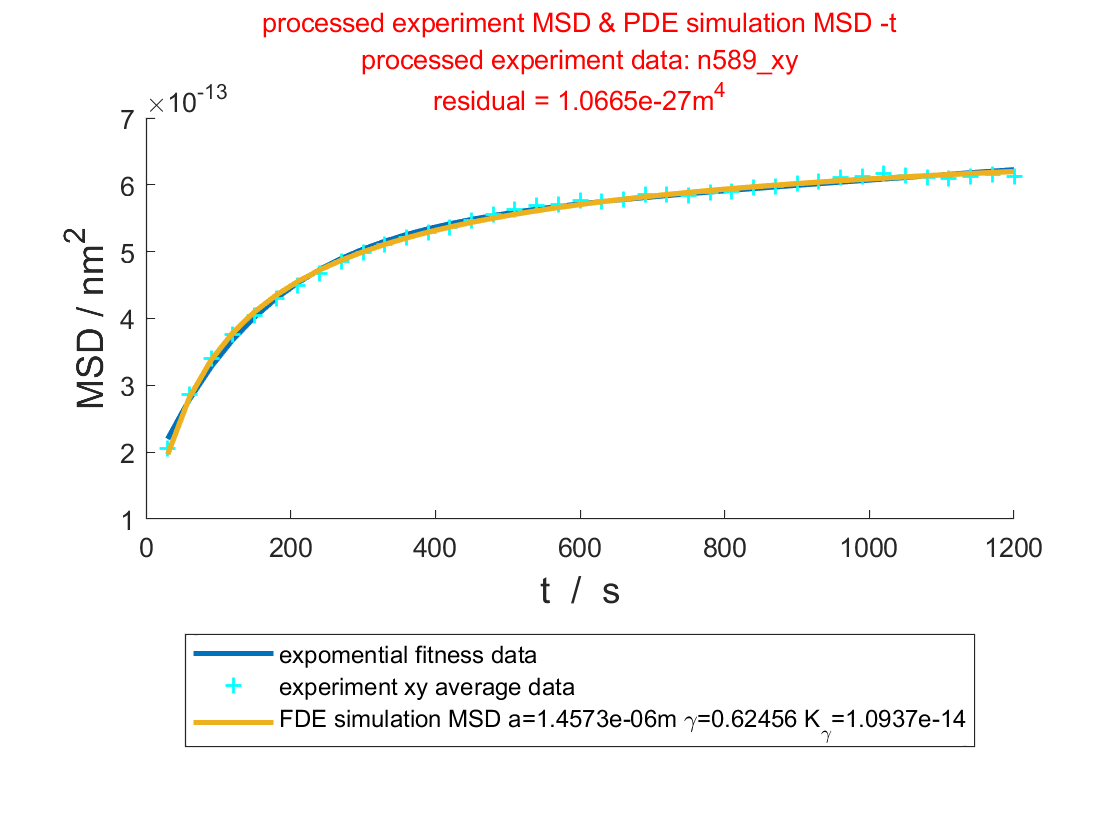

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
c=clock;
saveas(gcf,strrep([storage_location,'\image\FDEWRB-MSD ',data_name,'_',num2str(experiment_interval),'s ',num2str(c(1)),'.',num2str(c(2)),'.',num2str(c(3)),' ',num2str(c(4)),num2str(c(5)),'.jpg'],'       ',' '))